# 矩阵的重构和重新排列

`这一小节我们介绍一些和矩阵的重构或重新排列相关的函数。`

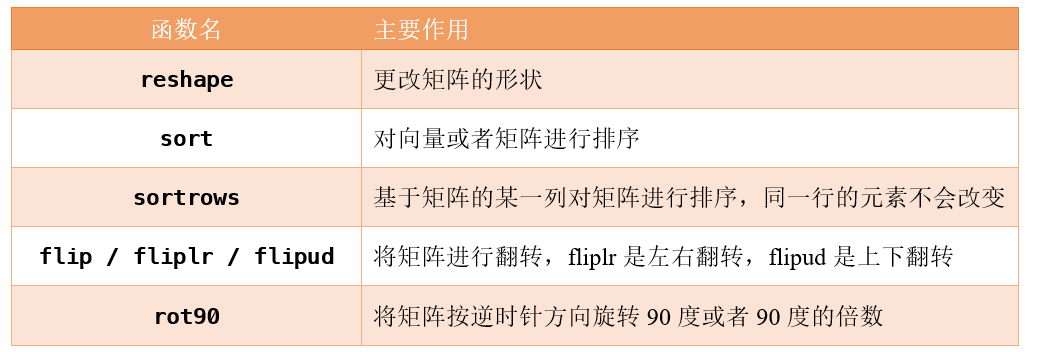

## **（1）reshape函数**

reshape`函数可以改变矩阵的形状，例如有一个矩阵`A`，它原来的大小是`2`行`6`列，我们需要将其形状变成`3`行`4`列，那么，我们可以使用命令：`reshape(A, 3, 4).  `（`A`和`B`中的元素个数是相同的）`

A = randi(10,2,6)

A =      7     8     7     8     3     1
     8     4     2     1     1     9


B = reshape(A,3,4)

B =      7     4     8     1
     8     7     1     1
     8     2     3     9


`从上面的运行结果可以看出，`reshape`函数实际上是按矩阵的线性索引来重新组织矩阵元素的。也就是说，它先取矩阵`A`的第一列，然后是第二列，依此类推，再按新的维度重新组织这些元素。因此，转换后的`B`矩阵中的元素和`A`矩阵中的元素是完全相同的，即`A(:)`和`B(:)`的结果完全相同。`

A(:)

ans =      7
     8
     8
     4
     7
     2
     8
     1
     3
     1


B(:)

ans =      7
     8
     8
     4
     7
     2
     8
     1
     3
     1


`若`A`是一个由`12`个元素组成的矩阵，命令`reshape(A,3,[ ])`、`reshape(A,[ ],4)`可以实现和`reshape(A,3,4)`一样的效果。`

A = 1:12;
reshape(A,3,[ ])

ans =      1     4     7    10
     2     5     8    11
     3     6     9    12


reshape(A,[ ],4)

ans =      1     4     7    10
     2     5     8    11
     3     6     9    12


reshape(A,3,4)

ans =      1     4     7    10
     2     5     8    11
     3     6     9    12


`如果你给出的转换后的行数和列数的乘积不等于原始矩阵中元素的个数，那么`MATLAB`就会报错：`

A = randi(10,2,6);

% 错误使用 reshape
% 元素数不能更改。请使用 [] 作为大小输入之一，以自动计算该维度的适当大小。
% B = reshape(A,3,5)

% 错误使用 reshape
% 已知维度的乘积 8 不能整除元素总数 12。
% B = reshape(A,[ ],8)

## **（2）sort函数**

**sort**`函数用来对向量或者矩阵进行排序。如果是矩阵的话，可以对矩阵的每一行或每一列分别进行排序。`

`第一：对向量v排序`

- `sort(v) 可以将向量v按照从小到大的顺序进行升序排列`

- `sort(v,'descend')可以将向量v按照从大到小的顺序进行降序排列`

v = [10 24 16 8 50 40];
v1 = sort(v)  

v1 =      8    10    16    24    40    50


v2 = sort(v,'descend')

v2 =     50    40    24    16    10     8


注意，上面的用法我们只使用了sort函数的一个返回值，即排序后的向量；

事实上，sort函数可以有两个返回值，基本用法为：[sort_v , ind] = sort(v)

这里，sort_v是排序后的向量，ind是排序后的向量中的每个元素在原始v向量中的索引（从1开始）。

v = [10 24 16 8 50 40];
[sort_v , ind] = sort(v)

sort_v =      8    10    16    24    40    50


ind =      4     1     3     2     6     5


`在上面的例子中，我们让`sort`函数返回了两个变量；`sort_v`和`ind`。它们是两个长度相等的向量，向量的方向和`sort`函数中输入的`v`向量的方向一致，都是行向量。向量`v`中所有元素的最小值为`8`，而`8`在`v`中的索引是`4`，因此`sort_v`中第一个元素为`8`，`ind`的第一个元素为`4`；` `向量`v`中第二小的值为`10`，而`10`是`v`中的第`1`个元素，因此`sort_v`中第二个元素为`10`，`ind`的第二个元素为`1`；依次类推，可以得到`sort_v`和`ind`向量的值。事实上，这里有一个恒等关系成立：`v(ind)`运行的结果和`sort_v`的结果完全一样，大家可以自行验证。`

v(ind)

ans =      8    10    16    24    40    50


`下面我们看一个具体的应用场景。``假设清风班上有`10`名同学，序号分别是`1`号、`2`号一直到`10`号。已知这`10`名同学的成绩构成的向量为：`[84 70 61 90 69 78 88 74 92 76]`，问：清风班上哪三名同学的分数最高，分数分别是多少`?

score = [84 70 61 90 69 78 88 74 92 76];
[sort_score, ind] = sort(score,'descend')

sort_score =     92    90    88    84    78    76    74    70    69    61


ind =      9     4     7     1     6    10     8     2     5     3


`根据`MATLAB`返回的结果可以看出：`9`号、`4`号和`7`号这三名同学的分数排名前三，分别是`92`、`90`和`88`分。`

***这里再引申一个问题：我们能不能知道这10名同学在班上的排名？***

(这个问题可能有点绕，大家课后可以多看几遍！)

`上面这个问题比较简单，我们再来提一个问题：我们能不能知道这`10`名同学在班上的排名？例如：`1`号同学`84`分，在班上排名第`4`；`2`号同学`70`分，在班上排名第`8`；`3`号同学`61`分，排名第`10`；`4`号同学`90`分，排名第`2`；……` `；依此类推，最终我们想要得到的排名为：`[4 8 10 2 9 5 3 7 1 6].

`大家观察`ind`的值和我们想得到的排名的值，应该可以发现如下规律：`1`号同学排名第`4`，而`ind`中等于`1`的元素的索引也为`4`；`2`号同学排名第`8`，而`ind`中等于`2`的元素的索引也为`8`；`3`号同学排名第`10`，而`ind`中等于`3`的元素的索引也为`10`；`4`号同学排名第`2`，而`ind`中等于`4`的元素的索引也为`2`，依次类推，我们可以根据`ind`得到想要的排名。`

`根据上面的分析，我们可以将`ind`这个向量按照从小到大的顺序排列，排序后的向量是`[1,2,3,`…`,10]`，且排序后的向量中的每个元素在向量`ind`中的索引就是我们要得到的排名`!

`因此，我们只需要加下面这行代码，`new_ind`就是我们想要计算的排名：`

[sort_ind, new_ind] = sort(ind)

sort_ind =      1     2     3     4     5     6     7     8     9    10


new_ind =      4     8    10     2     9     5     3     7     1     6


思考：上面这个代码还存在一个问题：如果存在同学的成绩相同的情况

例如： [60 80 80 70 50]

我们要得到答案：

普通排名：[4 1 1 3 5] 或者中国式排名 [3 1 1 2 4]

（普通排名的并列排名会占据名次的数字位置，而中国式排名中的并列排名不占用名次）

而上面的代码是满足不了这个需求的，我们需要使用其他的方法得到这个结果，这个问题超出了我们目前掌握的知识点。

这里稍微透漏一下，我们使用本章后面介绍的ismember函数可以解决这个问题。我们会将这个问题作为课后的作业题供大家练习。

[sort_score, ind] = sort([60 80 80 70 50],'descend')

sort_score =     80    80    70    60    50


ind =      2     3     4     1     5


[sort_ind, new_ind] = sort(ind)

sort_ind =      1     2     3     4     5


new_ind =      4     1     2     3     5


`第二：对矩阵A排序`

`使用方法：sort(A,dim)`

- `dim = 1时，沿着行方向`(`从上至下`)对矩阵的每一列按照从小到大的顺序分别进行排序

- `dim = 2时，沿着列方向`(`从左至右`)对矩阵的每一行按照从小到大的顺序分别进行排序

   `注意：（`1`）当`dim=1`时，`sort(A,1)`可以直接写成`sort(A)`；（`2`）默认是升序排列的，我们可以在最后面加一个输入参数`'descend'`，变成从大到小的降序排列；（`3`）可以有两个返回值，代表的含义和对向量排序类似，表示排序后的元素在原矩阵所在行或所在列中的索引。`

A = [4 1 8 7 8 2;
     3 7 8 6 4 2;
     8 7 8 4 7 6;
     1 6 3 1 8 5];

sort(A)  % 沿着行方向(从上至下)对矩阵的每一列按照从小到大的顺序分别进行排序

ans =      1     1     3     1     4     2
     3     6     8     4     7     2
     4     7     8     6     8     5
     8     7     8     7     8     6


sort(A,1)

ans =      1     1     3     1     4     2
     3     6     8     4     7     2
     4     7     8     6     8     5
     8     7     8     7     8     6


sort(A,'descend')  % 更改为降序排列

ans =      8     7     8     7     8     6
     4     7     8     6     8     5
     3     6     8     4     7     2
     1     1     3     1     4     2


sort(A,1,'descend')  % 更改为降序排列

ans =      8     7     8     7     8     6
     4     7     8     6     8     5
     3     6     8     4     7     2
     1     1     3     1     4     2


sort(A,2)  % dim = 2时，沿着列方向(从左至右)对矩阵的每一行按照从小到大的顺序分别进行排序

ans =      1     2     4     7     8     8
     2     3     4     6     7     8
     4     6     7     7     8     8
     1     1     3     5     6     8


sort(A,2,'descend')  % 更改为降序排列

ans =      8     8     7     4     2     1
     8     7     6     4     3     2
     8     8     7     7     6     4
     8     6     5     3     1     1


[sort_A , ind] = sort(A)

sort_A =      1     1     3     1     4     2
     3     6     8     4     7     2
     4     7     8     6     8     5
     8     7     8     7     8     6


ind =      4     1     4     4     2     1
     2     4     1     3     3     2
     1     2     2     2     1     4
     3     3     3     1     4     3


但这时候的A(ind)就不等于sort_A啦

A(ind)  % 全部由第一列元素构成

ans =      1     4     1     1     3     4
     3     1     4     8     8     3
     4     3     3     3     4     1
     8     8     8     4     1     8


## （3）sortrows函数

**sortrows**`函数可以基于矩阵的某一列对矩阵进行排序。排序后的新矩阵的同一行元素不会改变。``这个函数的用法较多，我们这里直接以一个具体的实例来讲解它的用法。`

假设清风老师有6名学生，每一行代表一名学生。这六名同学的四门科目的成绩对应着四列，例如第一名同学的第一科成绩为95，第二科成绩为80，依次类推。

score = [95    80    85    79   
         95    67    78    90    
         95    67    78    75   
         95    67    64    73   
         86    85    82    84    
         86    87    84    88];

请解决下面的问题：

（1）请基于第一科的成绩按升序对这六名同学进行排序。当第一科成绩相同时，基于第二科成绩升序排列。如果第二科成绩还相同，就基于第三科成绩进行排序，依次类推。

sort_score1 = sortrows(score)

sort_score1 =     86    85    82    84
    86    87    84    88
    95    67    64    73
    95    67    78    75
    95    67    78    90
    95    80    85    79


（2）请基于第一科的成绩按升序对这六名同学进行排序。当第一科成绩相同时，请保持其在矩阵中出现的先后顺序。

sort_score2 = sortrows(score,1)

sort_score2 =     86    85    82    84
    86    87    84    88
    95    80    85    79
    95    67    78    90
    95    67    78    75
    95    67    64    73


（3）请基于第二科的成绩按升序对这六名同学进行排序。当第二科成绩相同时，请保持其在矩阵中出现的先后顺序。

sort_score3 = sortrows(score,2)

sort_score3 =     95    67    78    90
    95    67    78    75
    95    67    64    73
    95    80    85    79
    86    85    82    84
    86    87    84    88


（4）请基于第一科的成绩按升序对这六名同学进行排序。**当第一科成绩相同时**，基于第三科成绩升序排列。如果第一科和第三科都相同，就保持在矩阵中出现的先后顺序。

sort_score4 = sortrows(score,[1,3])

sort_score4 =     86    85    82    84
    86    87    84    88
    95    67    64    73
    95    67    78    90
    95    67    78    75
    95    80    85    79


事实上，sortrows(score)等价于sortrows(score, 1:size(score,2))，即sortrows(score, [1,2,3,4])

（5）请基于第一科的成绩对这六名同学进行**降序排列**。当第一科成绩相同时，基于第三科成绩**降序排列**。如果第一科和第三科都相同，就保持在矩阵中出现的先后顺序。

sort_score5 = sortrows(score,[1,3],'descend')

sort_score5 =     95    80    85    79
    95    67    78    90
    95    67    78    75
    95    67    64    73
    86    87    84    88
    86    85    82    84


（6）请基于第一科的成绩对这六名同学进行**降序排列**。当第一科成绩相同时，基于第三科成绩**升序排列**。如果第一科和第三科都相同，就保持在矩阵中出现的先后顺序。

sort_score6 = sortrows(score,[1,3],{'descend','ascend'})

sort_score6 =     95    67    64    73
    95    67    78    90
    95    67    78    75
    95    80    85    79
    86    85    82    84
    86    87    84    88


（7）请基于第一科的成绩按升序对这六名同学进行排序。当第一科成绩相同时，请保持其在矩阵中出现的先后顺序，并返回索引值。

score

score =     95    80    85    79
    95    67    78    90
    95    67    78    75
    95    67    64    73
    86    85    82    84
    86    87    84    88


[sort_score7 , ind7] = sortrows(score,1)

sort_score7 =     86    85    82    84
    86    87    84    88
    95    80    85    79
    95    67    78    90
    95    67    78    75
    95    67    64    73


ind7 =      5
     6
     1
     2
     3
     4


注意：score(ind7,:)得到的结果和sort_score7的结果完全一样。

score(ind7,:)

ans =     86    85    82    84
    86    87    84    88
    95    80    85    79
    95    67    78    90
    95    67    78    75
    95    67    64    73


通过上面的例子可以看出，sortrows函数和sort函数的最大区别在于：

sort`函数会对矩阵的每一列分别进行排序；`

sortrows`函数是基于某一列进行排序的，排序后得到的新矩阵的同一行元素不会改变。`

score

score =     95    80    85    79
    95    67    78    90
    95    67    78    75
    95    67    64    73
    86    85    82    84
    86    87    84    88


sort(score)

ans =     86    67    64    73
    86    67    78    75
    95    67    78    79
    95    80    82    84
    95    85    84    88
    95    87    85    90


sortrows(score)

ans =     86    85    82    84
    86    87    84    88
    95    67    64    73
    95    67    78    75
    95    67    78    90
    95    80    85    79


sortrows(score,[1:4])

ans =     86    85    82    84
    86    87    84    88
    95    67    64    73
    95    67    78    75
    95    67    78    90
    95    80    85    79


sortrows(score,1:4)

ans =     86    85    82    84
    86    87    84    88
    95    67    64    73
    95    67    78    75
    95    67    78    90
    95    80    85    79


在实际的应用场景中，sort函数一般只用于对向量进行排序；如果是矩阵或者表格排序，我们一般使用sortrows函数，例如Excel中对表格的排序就和sortrows函数类似。在以后的章节中，我们会专门讲到MATLAB中的表格数据，到时候还会用的这个函数。

## **（4）flip / fliplr / flipud函数**

这三个函数用于对矩阵进行翻转

[flip](https://ww2.mathworks.cn/help/matlab/ref/flip.html)：翻转元素的顺序； [fliplr](https://ww2.mathworks.cn/help/matlab/ref/fliplr.html)：将数组从左向右翻转 ；[flipud](https://ww2.mathworks.cn/help/matlab/ref/flipud.html)：将数组从上向下翻转

后面两个函数是flip函数的特例。

**用法1： flip(A)**

- 如果 A 为向量，flip(A) 将沿向量的长度方向翻转元素顺序。

- 如果 A 为矩阵，flip(A) 将反转每列元素的顺序。

A = [5 2 7 8 9];  % 行向量
flip(A)

ans =      9     8     7     2     5


等价于  A(end:-1:1)

A(end:-1:1)

ans =      9     8     7     2     5


B = [5;2;7;8;9];  % 列向量
flip(B)

ans =      9
     8
     7
     2
     5


C = [5 8 7;
     4 2 6; 
     3 5 8;
     6 4 1];
flip(C)

ans =      6     4     1
     3     5     8
     4     2     6
     5     8     7


**用法2： flip(A,dim)**

flip(A,dim) 沿维度 dim 翻转 A 中元素的顺序。

如果 A 为矩阵，flip(A,1) 将沿着行方向对矩阵A上下翻转，

                          flip(A,2) 将沿着列方向对矩阵A左右翻转。

C = [5 8 7;
     4 2 6; 
     3 5 8;
     6 4 1];
flip(C,1)   % 等价于flip(C) 或者  flipud(C)

ans =      6     4     1
     3     5     8
     4     2     6
     5     8     7


flipud(C)

ans =      6     4     1
     3     5     8
     4     2     6
     5     8     7


 flip(C,2)   %  fliplr(C)

ans =      7     8     5
     6     2     4
     8     5     3
     1     4     6


 fliplr(C)

ans =      7     8     5
     6     2     4
     8     5     3
     1     4     6


A = 1:5

A =      1     2     3     4     5


flip(A)

ans =      5     4     3     2     1


flip(A,1)

ans =      1     2     3     4     5


## **（5）rot90函数**  

允许按90°或其倍数逆时针旋转矩阵

C = [5 8 7; 4 2 6; 3 5 8; 6 4 1]

C =      5     8     7
     4     2     6
     3     5     8
     6     4     1


rot90(C)  % 逆时针方向旋转90度；不提供倍数时默认为1，等价于rot90(C,1)

ans =      7     6     8     1
     8     2     5     4
     5     4     3     6


% 旋转倍数只能是整数
rot90(C,2)  % 逆时针方向旋转90*2=180度

ans =      1     4     6
     8     5     3
     6     2     4
     7     8     5


rot90(C,3)  % 逆时针方向旋转90*3=270度

ans =      6     3     4     5
     4     5     2     8
     1     8     6     7


rot90(C,-1)  % 逆时针旋转-90度；等价于顺时针旋转90度

ans =      6     3     4     5
     4     5     2     8
     1     8     6     7


配套的讲解视频可在b站免费观看：

《MATLAB教程新手入门篇（数学建模清风主讲，适合零基础同学观看）》

[https://www.bilibili.com/video/BV1dN4y1Q7Kt/](https://www.bilibili.com/video/BV1dN4y1Q7Kt/)